# Getting Started with RocketPy in MATLAB®

In this Live Script, you will learn how to run RocketPy using the MATLAB® environment.

We start by configuring the Python environment. You can do so by following the guidelines presented in the MATLAB® documentation: [Configure Your System to Use Python - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html?searchHighlight=python&s_tid=srchtitle_python_4).

Once the Python environment is configured, RocketPy needs to installed using `pip` as outlined in RocketPy's documentation: [Installation — RocketPy documentation](https://docs.rocketpy.org/en/latest/user/installation.html#quick-install-using-pip).

Finally, all the prerequisites are complete and you can comeback to MATLAB®! We just need to set the execution mode as out of process and start working. MATLAB® can run Python scripts and functions in a separate process. Running Python in a separate process enables you to:

- Use some third-party libraries in the Python code that are not compatible with MATLAB®.

- Isolate the MATLAB process from crashes in the Python code.

pyenv('ExecutionMode','OutOfProcess');

Now, we will go through a simplified rocket trajectory simulation to get you started. Let's start by importing the rocketpy module.

rocketpy = py.importlib.import_module('rocketpy');

## Setting Up a Simulation

Creating an Environment for Spaceport America

% rocketpy.Environment(railLength, latitude, longitude, elevation);
Env = rocketpy.Environment(pyargs(...
    'railLength', 5.2, ...
    'latitude', 32.990254, ...
    'longitude',-106.974998, ...
    'elevation', 1400 ...
));

To get weather data from the GFS forecast, available online, we run the following lines.

First, we set tomorrow's date.

Tomorrow = datetime('tomorrow');
Env.setDate({int32(Tomorrow.Year), int32(Tomorrow.Month), int32(Tomorrow.Day), int32(12)}) % Hour given in UTC time (noon UTC)

Now, we tell our Environment object to retrieve a weather forecast for our specified location and date using GFS:

Env.setAtmosphericModel(pyargs( ...
    'type', "Forecast", ...
    'file', "GFS" ...
))

We can see what the weather will look like by calling the info method!

Env.info()

Launch Site Details

Launch Rail Length: 5.2  m
Launch Date: 2022-03-04 12:00:00 UTC
Launch Site Latitude: 32.99025°
Launch Site Longitude: -106.97500°
Reference Datum: SIRGAS2000
Launch Site UTM coordinates: 315468.64 W    3651938.65 N
Launch Site UTM zone: 13S
Launch Site Surface Elevation: 1471.5 m


Atmospheric Model Details

Atmospheric Model Type: Forecast
Forecast Maximum Height: 79.574 km
Forecast Time Period: From  2022-03-03 12:00:00  to  2022-03-19 12:00:00  UTC
Forecast Hour Interval: 3  hrs
Forecast Latitude Range: From  -90.0 ° To  90.0 °
Forecast Longitude Range: From  0.0 ° To  359.75 °


Surface Atmospheric Conditions

Surface Wind Speed: 5.93 m/s
Surface Wind Direction: 154.94°
Surface Wind Heading: 334.94°
Surface Pressure: 852.14 hPa
Surface Temperature: 286.00 K
Surface Air Density: 1.038 kg/m³
Surface Speed of Sound: 339.02 m/s


Atmospheric Model Plots


Plots will open in a separate window, so be sure to run this last cell to seem them!

## Creating a Motor

A solid rocket motor is used in this case. To create a motor, the SolidMotor class is used and the required arguments are given.

The SolidMotor class requires the user to have a thrust curve ready. This can come either from a .eng file for a commercial motor, such as below, or a .csv file from a static test measurement.

Besides the thrust curve, other parameters such as grain properties and nozzle dimensions must also be given.

Pro75M1670 = rocketpy.SolidMotor(pyargs( ...
    'thrustSource', "../../data/motors/Cesaroni_M1670.eng", ...
    'burnOut', 3.9, ...
    'grainNumber', int32(5), ...
    'grainSeparation', 5 / 1000, ...
    'grainDensity', 1815, ...
    'grainOuterRadius', 33 / 1000, ...
    'grainInitialInnerRadius', 15 / 1000, ...
    'grainInitialHeight', 120 / 1000, ...
    'nozzleRadius', 33 / 1000, ...
    'throatRadius', 11 / 1000, ...
    'interpolationMethod', "linear" ...
));

To see what our thrust curve looks like, along with other import properties, we invoke the info method yet again. You may try the allInfo method if you want more information all at once!

Pro75M1670.info()


Motor Details
Total Burning Time: 3.9 s
Total Propellant Mass: 2.956 kg
Propellant Exhaust Velocity: 2038.745 m/s
Average Thrust: 1545.218 N
Maximum Thrust: 2200.0 N at 0.15 s after ignition.
Total Impulse: 6026.350 Ns

Plots


Plots will open in a separate window, so be sure to run this last cell to seem them!

## Creating a Rocket

A rocket is composed of several components. Namely, we must have a motor (good thing we have the Pro75M1670 ready), a couple of aerodynamic surfaces (nose cone, fins and tail) and parachutes (if we are not launching a missile).

Let's start by initializing our rocket, named Calisto, supplying it with the Pro75M1670 engine, entering its inertia properties, some dimensions and also its drag curves.

Calisto = rocketpy.Rocket(pyargs( ...
    'motor', Pro75M1670, ...
    'radius', 127 / 2000, ...
    'mass', 19.197 - 2.956, ...
    'inertiaI', 6.60, ...
    'inertiaZ', 0.0351, ...
    'distanceRocketNozzle', -1.255, ...
    'distanceRocketPropellant', -0.85704, ...
    'powerOffDrag', "../../data/calisto/powerOffDragCurve.csv", ...
    'powerOnDrag', "../../data/calisto/powerOnDragCurve.csv" ...
));

Calisto.setRailButtons([0.2, -0.5])

### Adding Aerodynamic Surfaces

Now we define the aerodynamic surfaces. They are really straight forward.

NoseCone = rocketpy.Rocket.addNose(pyargs( ...
    'self', Calisto, ...
    'length', 0.55829, ...
    'kind', "vonKarman", ...
    'distanceToCM', 0.71971 ...
));

FinSet = rocketpy.Rocket.addFins(pyargs( ...
    'self', Calisto, ...
    'n', int32(4), ...
    'span', 0.100, ...
    'rootChord', 0.120, ...
    'tipChord', 0.040, ...
    'distanceToCM', -1.04956 ...
));

Tail = rocketpy.Rocket.addTail(pyargs( ...
    'self', Calisto, ...
    'topRadius', 0.0635, ...
    'bottomRadius', 0.0435, ...
    'length', 0.060, ...
    'distanceToCM', -1.194656 ...
));

### Adding Parachutes

Finally, we have parachutes! Calisto will have two parachutes, Drogue and Main.

Both parachutes are activated by some special algorithm, which is usually really complex and a trade secret. Most algorithms are based on pressure sampling only, while some also use acceleration info.

RocketPy allows you to define a trigger function which will decide when to activate the ejection event for each parachute. This trigger function is supplied with pressure measurement at a predefined sampling rate. This pressure signal is usually noisy, so artificial noise parameters can be given. Call 

% py.help(rocketpy.Rocket.addParachute)

for more details. Furthermore, the trigger function also receives the complete state vector of the rocket, allowing us to use velocity, acceleration or even attitude to decide when the parachute event should be triggered.

Here, we define our trigger functions rather simply using Python. Unfortunately, defining these with MATLAB code is not yet possible.

% Drogue parachute is triggered when vertical velocity is negative, i.e. rocket is falling past apogee
drogueTrigger = py.eval("lambda p, y: y[5] < 0", py.dict);

% Main parachute is triggered when vertical velocity is negative and altitude is below 800 AGL 
mainTrigger = py.eval("lambda p, y: (y[5] < 0) and (y[2] < 800 + 1400)", py.dict); 

Now we add both the drogue and the main parachute to our rocket.

Main = rocketpy.Rocket.addParachute(pyargs( ...
    'self', Calisto, ...
    'name', "Main", ...
    'CdS', 10.0, ...
    'trigger', mainTrigger, ...
    'samplingRate', 105, ...
    'lag', 1.5, ...
    'noise', py.tuple({0, 8.3, 0.5}) ...
));

Drogue = rocketpy.Rocket.addParachute(pyargs( ...
    'self', Calisto, ...
    'name', "Drogue", ...
    'CdS', 1.0, ...
    'trigger', drogueTrigger, ...
    'samplingRate', 105, ...
    'lag', 1.5, ...
    'noise', py.tuple({0, 8.3, 0.5}) ...
));

`Just be careful if you run this last cell multiple times! If you do so, your rocket will end up with lots of parachutes which activate together, which may cause problems during the flight simulation. We advise you to re-run all cells which define our rocket before running this, preventing unwanted old parachutes. Alternatively, you can run the following lines to remove parachutes.`

% Calisto.parachutes.remove(Drogue)
% Calisto.parachutes.remove(Main)

## `Simulating a Flight`

`Simulating a flight trajectory is as simples as initializing a Flight class object givin the rocket and environnement set up above as inputs. The launch rail inclination and heading are also given here.`

TestFlight = rocketpy.Flight(pyargs(...
    'rocket', Calisto, ...
    'environment',Env, ...
    'inclination', 85, ...
    'heading', 0 ...
));

## `Analyzing the Results`

`RocketPy gives you many plots, thats for sure! They are divided into sections to keep them organized. Alternatively, see the Flight class documentation to see how to get plots for specific variables only, instead of all of them at once.`

TestFlight.allInfo()

Initial Conditions

Position - x: 0.00 m | y: 0.00 m | z: 1471.47 m
Velocity - Vx: 0.00 m/s | Vy: 0.00 m/s | Vz: 0.00 m/s
Attitude - e0: 0.999 | e1: -0.044 | e2: 0.000 | e3: -0.000
Euler Angles - Spin φ : 0.00° | Nutation θ: -5.00° | Precession ψ: -0.00°
Angular Velocity - ω1: 0.00 rad/s | ω2: 0.00 rad/s| ω3: 0.00 rad/s


Launch Rail Orientation

Launch Rail Inclination: 85.00°
Launch Rail Heading: 0.00°


Surface Wind Conditions

Frontal Surface Wind Speed: 5.37 m/s
Lateral Surface Wind Speed: 2.51 m/s


 Rail Departure State

Rail Departure Time: 0.363 s
Rail Departure Velocity: 25.800 m/s
Rail Departure Static Margin: 2.133 c
Rail Departure Angle of Attack: 13.148°
Rail Departure Thrust-Weight Ratio: 10.143
Rail Departure Reynolds Number: 1.927e+05


BurnOut State

BurnOut time: 3.900 s
Altitude at burnOut: 660.034 m (AGL)
Rocket velocity at burnOut: 280.019 m/s
Freestream velocity at burnOut: 279.862 m/s
Mach Number at burnOut: 0.831
Kinetic energy at burnOut: 6.367e+05 J


Apogee


Plots will open in a separate window, so be sure to run this last cell to seem them!

## Working with Data Generated by RocketPy in MATLAB

You can access the entire trajectory solution matrix with the following line of code. The returned matrix contain the following columns: time $t$ (s), $x$ (m), $y$ (m), $z$ (m), $v_x$ (m/s), $v_y$ (m/s), $v_z$ (m/s), $q_0$, $q_1$, $q_2$, $q_3$,  $\omega_1$ (rad/s), $\omega_2$ (rad/s), $\omega_3$ (rad/s).

solution_matrix = double(py.numpy.array(TestFlight.solution))

solution_matrix = 	1.0e+03 *

         0         0         0    1.4715         0         0         0    0.0010   -0.0000         0         0         0         0         0
    0.0000         0         0    1.4715         0         0         0    0.0010   -0.0000         0         0         0         0         0
    0.0000         0         0    1.4715         0         0         0    0.0010   -0.0000         0         0         0         0         0
    0.0000         0         0    1.4715         0         0         0    0.0010   -0.0000         0         0         0         0         0
    0.0000         0         0    1.4715         0         0         0    0.0010   -0.0000         0         0         0         0         0
    0.0000         0         0    1.4715         0         0         0    0.0010   -0.0000         0         0         0         0         0
    0.0000         0         0    1.4715         0         0         0    0.0010   -0.0000         0         0         0    

Support for accessing secondary values calculated during post processing, such as energy, mach number, and angle of attack, is also available for all versions of RocketPy greater or equal to version 0.11.0.

To showcase this, let's get the angle of attack of the rocket and plot it using MATLAB:

angle_of_attack = double(TestFlight.angleOfAttack.source)

angle_of_attack =          0   94.5286
    0.0014   94.5286
    0.0028   94.5286
    0.0056   94.5286
    0.0085   94.5286
    0.0113   94.5286
    0.0395   94.5286
    0.0409   94.5286
    0.0422   94.5286
    0.0450   94.5286


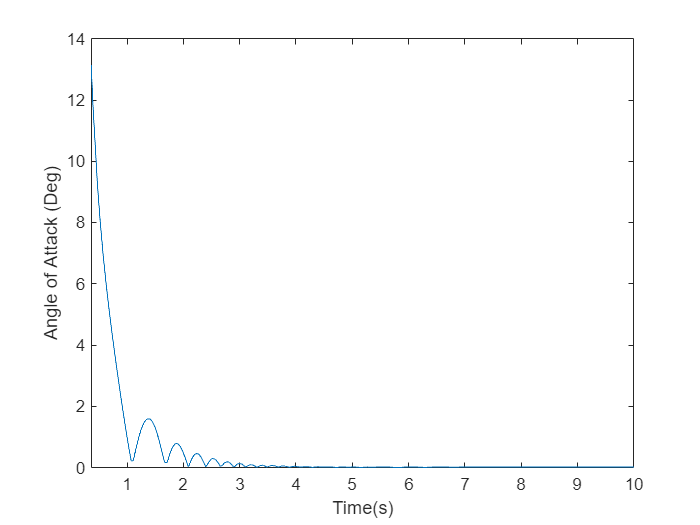

plot(angle_of_attack(:,1), angle_of_attack(:,2)) % First column is time (s), second is the angle of attack
ylabel('Angle of Attack (Deg)')
xlabel('Time(s)')
xlim([TestFlight.outOfRailTime, 10])

You can also convert data from other objects besides the Flight class, such as from the Environment. For example, let's say you want to get the wind velocity, both the x and y component:

wind_velocity_x = double(Env.windVelocityX.source) % First column is altitude (ASL m), while the second one is the speed (m/s)

wind_velocity_x = 	1.0e+04 *

    0.0119   -0.0002
    0.0334   -0.0002
    0.0554   -0.0002
    0.0780   -0.0002
    0.1011   -0.0002
    0.1492   -0.0003
    0.1999    0.0003
    0.2531    0.0006
    0.3090    0.0011
    0.3682    0.0017


wind_velocity_y = double(Env.windVelocityY.source) % First column is altitude (ASL m), while the second one is the speed (m/s)

wind_velocity_y = 	1.0e+04 *

    0.0119    0.0005
    0.0334    0.0005
    0.0554    0.0005
    0.0780    0.0005
    0.1011    0.0005
    0.1492    0.0005
    0.1999    0.0010
    0.2531    0.0010
    0.3090    0.0010
    0.3682    0.0009


## Time to Fly!

This is all you need to get started using RocketPy in MATLAB! Now it is time to play around and create amazing rockets. Have a great launch!